clear

% this is a 5G PRACH format 0 transmission
L=839

L = 839


% this is number of samples per bin, floor(L/Ncs) gives the number of cyclic shifts, see below
Ncs=26

Ncs = 26

% this is the FFT size for the generation/reception of PRACH
N=49152

N = 49152

% this is the length of the cyclic prefix for PRACH
Ncp=6336

Ncp = 6336



% 6-bit data messages for 3 transmitters / UEs
preamble_index1=0;
preamble_index2=1;
preamble_index3=35;% 

% up to 6 Zadoff-Chu root sequences for this format
utab=[129 710 140 699 120 719]

utab =    129   710   140   699   120   719


% number of cyclic shifts
nshifts = floor(L/Ncs);
% number of Zadoff-Chu sequences required
nseq = ceil(64/nshifts);

% index of the preamble sequence to use
uind1=floor(preamble_index1/nshifts)

uind1 = 0

uind2=floor(preamble_index2/nshifts)

uind2 = 0

uind3=floor(preamble_index3/nshifts)

uind3 = 1

% index of cyclic shift to use
nuind1=rem(preamble_index1,nshifts)

nuind1 = 0

nuind2=rem(preamble_index2,nshifts)

nuind2 = 1

nuind3=rem(preamble_index3,nshifts)

nuind3 = 3


if (uind1>=length(utab) || uind2>=length(utab) || uind3>=length(utab)) 
    fprintf("ERROR tab length %d : %d %d %d",length(utab),uind1,uind1,uind3) 
end

% These are the Zadoff-Chu Sequence generators (time-domain) 
% for the 3 transmitters
xu1 = exp(-j*pi*utab(1+uind1)*(0:838).*(1:839)/839);
xu2 = exp(-j*pi*utab(1+uind2)*(0:838).*(1:839)/839);
xu3 = exp(-j*pi*utab(1+uind3)*(0:838).*(1:839)/839);

% implement cyclic-shifts
% Note we do this in the time-domain and then do an 839-point fft here in MATLAB
% This is not usually done in practice because of the complexity of the FFT (i.e. a large prime number)
% There is a way to compute the Fourier transform directly and then perform the cyclic shift by a multiplication of a phasor in the frequency-domain.

ZC_seq1 = exp(-j*pi*utab(1+0)*(0:838).*(1:839)/839);
ZC_seq1 = fft(ZC_seq1);
ZC_seq2 = exp(-j*pi*utab(1+1)*(0:838).*(1:839)/839);
ZC_seq2 = fft(ZC_seq2);
xuv1 = xu1; 
xuv2 = xu2;
xuv3 = xu3;

Yuv1 = fft(xuv1);
Yuv2 = fft(xuv2);
Yuv3 = fft(xuv3);

for n=0:838
    xuv1(n+1) = xu1(1+rem(n+(Ncs*nuind1),839));
    yuv1 = fft(xuv1);
    xuv2(n+1) = xu2(1+rem(n+(Ncs*nuind2),839));
    yuv2 = fft(xuv2);
    xuv3(n+1) = xu3(1+rem(n+(Ncs*nuind3),839));
    yuv3 = fft(xuv3);
end



% put the PRACH in the lowest frequency (positive) subcarriers starting at carrier 7
Xuv1 = zeros(1,49152);
Xuv1(7+(1:839)) = yuv1;
Xuv2 = zeros(1,49152);
Xuv2(7+(1:839)) = yuv2;
Xuv3 = zeros(1,49152);
Xuv3(7+(1:839)) = yuv3;

% bring to time-domain
xuv1_49152 = ifft(Xuv1);
xuv2_49152 = ifft(Xuv2);
xuv3_49152 = ifft(Xuv3);

% add cyclic prefix
xuv1_49152 = [xuv1_49152((49152-6335):end) xuv1_49152];
xuv2_49152 = [xuv2_49152((49152-6335):end) xuv2_49152];
xuv3_49152 = [xuv3_49152((49152-6335):end) xuv3_49152];

% normalizes the transmit signal to unit-energy
xuv1_49152 = xuv1_49152/sqrt(sum(abs(xuv1_49152).^2)/length(xuv1_49152));
en1=mean(abs(xuv1_49152).^2)

en1 = 1.0000

xuv2_49152 = xuv2_49152/sqrt(sum(abs(xuv2_49152).^2)/length(xuv2_49152));
en2=mean(abs(xuv2_49152).^2)

en2 = 1.0000

xuv3_49152 = xuv3_49152/sqrt(sum(abs(xuv3_49152).^2)/length(xuv3_49152));
en3=mean(abs(xuv3_49152).^2)

en3 = 1.0000

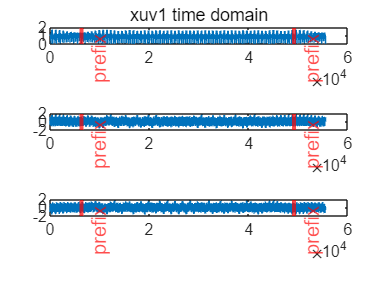


% store the 'standard' signal
xuv_1 = xuv1_49152;
xuv_2 = xuv2_49152;
xuv_3 = xuv3_49152;

% Plot the time-domain and frequency-domain waveform (xuv1)
figure
subplot(3,1,1)
plot(abs(xuv1_49152))
xline(6336,'r--',"LineWidth",2,'Label','prefix')
xline(49152,'r--',"LineWidth",2,'Label','prefix')
title("xuv1 time domain")
subplot(3,1,2)
plot(real(xuv1_49152))
xline(6336,'r--',"LineWidth",2,'Label','prefix')
xline(49152,'r--',"LineWidth",2,'Label','prefix')
subplot(3,1,3)
plot(imag(xuv1_49152))
xline(6336,'r--',"LineWidth",2,'Label','prefix')
xline(49152,'r--',"LineWidth",2,'Label','prefix')

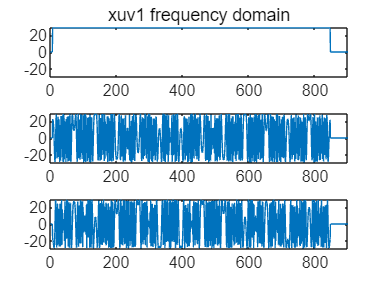


figure
subplot(3,1,1)
plot(abs(Xuv1))
axis([0 900 -30 30])
title("xuv1 frequency domain")
subplot(3,1,2)
plot(real(Xuv1))
axis([0 900 -30 30])
subplot(3,1,3)
plot(imag(Xuv1))
axis([0 900 -30 30])


% Question: What can you say regarding the frequency span (approximately how many PRBs does this waveform occupy

% Answer: One PRB contains 12 resource elements, which is, 12 subcarriers. The
% PRACH signal spans 839 REs, that is, approximately, 839/12 = 70 PRBs.

% simulate time-delay
delay1=30*3;
delay2=30*6;
delay3=30*9;
delaymax = 1+max([delay1 delay2 delay3]);
xuv1_49152 = [zeros(1,delay1) xuv1_49152 zeros(1,delaymax-delay1)];
xuv2_49152 = [zeros(1,delay2) xuv2_49152 zeros(1,delaymax-delay2)];
xuv3_49152 = [zeros(1,delay3) xuv3_49152 zeros(1,delaymax-delay3)];

SNR=0;
snr=10.^(.1*SNR);
noise1 = sqrt(.5/snr)*(randn(1,length(xuv1_49152))+sqrt(-1)*randn(1,length(xuv1_49152)));
noise2 = sqrt(.5/snr)*(randn(1,length(xuv1_49152))+sqrt(-1)*randn(1,length(xuv1_49152)));
rxsig1_justnoise = xuv1_49152 + noise1;
rxsig2_justnoise = xuv1_49152 + xuv2_49152 + xuv3_49152 + noise2;

% do TDL-C channel generation
fs=61.44e6;
SCS=30e3;
DS=300e-9;

H=get_tdl(fs,SCS,[0:105],DS,'tdlc');
H2 = zeros(1,2048);
halflength =53*12;
H2((2048-(halflength-1)):2048) = H(1:halflength);
H2(1:halflength) = H(halflength+(1:halflength));
h1 = ifft(H2)*sqrt(2048);

H=get_tdl(fs,SCS,[0:105],DS,'tdlc');
H2 = zeros(1,2048);
halflength =53*12;
H2((2048-(halflength-1)):2048) = H(1:halflength);
H2(1:halflength) = H(halflength+(1:halflength));
h2 = ifft(H2)*sqrt(2048);

H=get_tdl(fs,SCS,[0:105],DS,'tdlc');
H2 = zeros(1,2048);
halflength =53*12;
H2((2048-(halflength-1)):2048) = H(1:halflength);
H2(1:halflength) = H(halflength+(1:halflength));
h3 = ifft(H2)*sqrt(2048);

rxsig3_noiseandchannel = conv(h1,xuv1_49152);
rxsig3_noiseandchannel = rxsig3_noiseandchannel + sqrt(.5/snr)*(randn(1,length(rxsig3_noiseandchannel))+sqrt(-1)*randn(1,length(rxsig3_noiseandchannel)));

rxsig4_noiseandchannel = conv(h1,xuv1_49152) + conv(h2,xuv2_49152) + conv(h3,xuv3_49152);
rxsig4_noiseandchannel = rxsig4_noiseandchannel + sqrt(.5/snr)*(randn(1,length(rxsig4_noiseandchannel))+sqrt(-1)*randn(1,length(rxsig4_noiseandchannel)));

% What to do now
% a) implement the receiver using a frequency-domain correlation
% using the Zadoff-Chu sequences generation method as above
% b) show how the data detection and time-delay estimation

Prefix_len = 6336;
rx_sig = rxsig4_noiseandchannel;
xuv_N = [xuv_1;xuv_2;xuv_3];
search_bins = [nuind1, nuind2, nuind3];
search_preambles = [preamble_index1, preamble_index2, preamble_index3];
% % Act as a gNodeB, we might need to generate 64 sequences to indentify and
% % detect what signals the UE sends, then furthur locate and extract more
% % information about it.
% % Here for simplification, we assume that what we recieve is the same
% slot that UE sends PRACH and simplify the procedure to determine the
% preambles that use the root sequences we generated previously
% accordingly. 


Rx_sig = rx_sig;
%detect_pos = pos;
Start = 1+Prefix_len;
End = Start+49152-1;
PRACH_t = Rx_sig(Start:End);
PRACH_f = (fft(PRACH_t,[],2));
figure
fx = 1:49152;%linspace(-49152/2,49152/2,49152);
% plotPRACH_together(fx,abs(PRACH_f'))
PRACH_ff = PRACH_f(7+(1:839));
% plotPRACH_together(1:839,real(PRACH_ff'))
% plotPRACH_together(1:839,abs(PRACH_ff'))
% plot(fx,abs(PRACH_f(2,:)))
% plot(fx,abs(PRACH_f(3,:)))


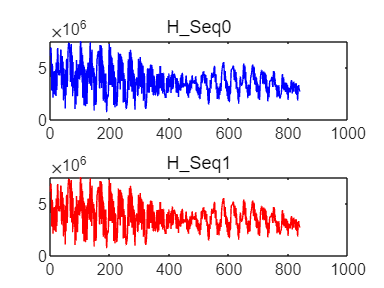

xu_N = [xu1;xu2;xu3];
yuv_N = [yuv1;yuv2;yuv3];
Yuv_N = [Yuv1;Yuv2;Yuv3];
Z = [ZC_seq1; ZC_seq2];
H_N = conj(Z) .* PRACH_ff;
plotH_together(1:839,abs(H_N)')

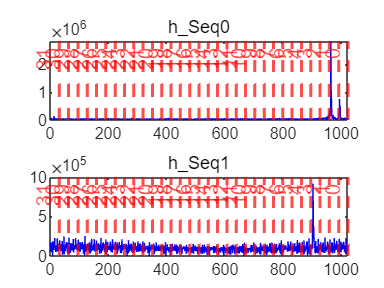

H_N = [H_N,zeros(2,1024-839)];
h_N = (ifft(H_N,1024,2));
h_N = circshift(h_N,-32,2);
ploth_together(1:1024,abs(h_N)')

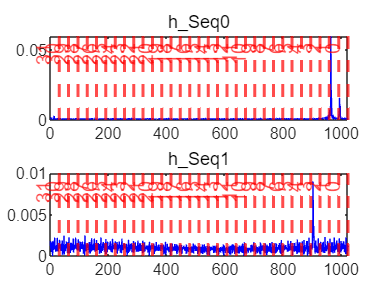

h_N_norm(1,:) = abs(h_N(1,:))./sum(abs(h_N(1,:)));
h_N_norm(2,:) = abs(h_N(2,:))./sum(abs(h_N(2,:)));
ploth_together(1:1024,h_N_norm')

[~,b1]=findpeaks(h_N_norm(1,:),'MinPeakHeight',6e-3);
[~,b2]=findpeaks(h_N_norm(2,:),'MinPeakHeight',6e-3);
B = [b1 b2];

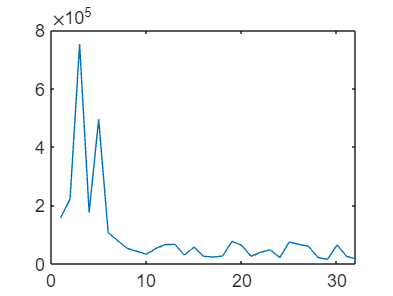

The timing advance for preamble 0 = 2.9297μs


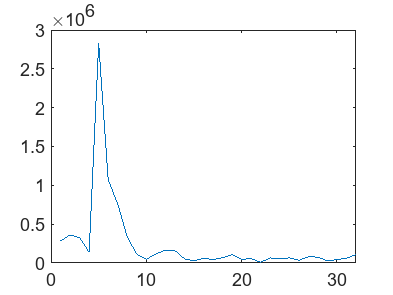

The timing advance for preamble 1 = 5.8594μs


%calculate the timing advance
sample_rate = 61.44; 
Time_Adv = [];
Detect_preambles = [];
if ~isempty(b1)
    Search_bin = 32-ceil(b1/32);
    [uniqueArr, ~, idx] = unique(Search_bin); % unique value
    count = histcounts(idx, 1:length(uniqueArr)+1); 
    Search_Bin = uniqueArr(count >= 1);

    for i = 1:length(Search_Bin)
    Search_preamble = Search_Bin(i);
    Detect_preambles = [Detect_preambles Search_preamble];
    Search_bin_index = 1024-(Search_Bin(i)+1)*32+1 : 1024-(Search_Bin(i))*32;
    Bin = h_N(1,Search_bin_index);
    [pk,loc] = max(Bin);
    figure
    plot(1:32, abs(Bin))
    time_adv = (loc-1)*49152/1024/sample_rate*2.*0.9375;
    Time_Adv = [Time_Adv, time_adv];
    Disp = ['The timing advance for preamble ' num2str(Search_preamble) ' = ' num2str(time_adv) 'μs'];
    disp(Disp)
    end
end

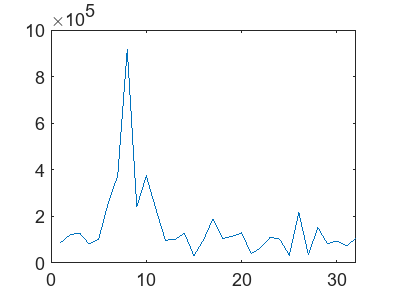

The timing advance for preamble 35 = 10.9375μs


if ~isempty(b2)
    Search_bin = 32-ceil(b2/32);
    [uniqueArr, ~, idx] = unique(Search_bin); % unique value
    count = histcounts(idx, 1:length(uniqueArr)+1); 
    Search_Bin = uniqueArr(count >= 1);

    for i = 1:length(Search_Bin)
    Search_preamble = Search_Bin(i)+32;
    Detect_preambles = [Detect_preambles Search_preamble];
    Search_bin_index = 1024-(Search_Bin(i)+1)*32+1 : 1024-(Search_Bin(i))*32;
    Bin = h_N(2,Search_bin_index);
    [pk,loc] = max(Bin);
    figure
    plot(1:32, abs(Bin))
    time_adv = (loc-1)*49152/1024/sample_rate*2;
    Time_Adv = [Time_Adv, time_adv];
    Disp = ['The timing advance for preamble ' num2str(Search_preamble) ' = ' num2str(time_adv) 'μs'];
    disp(Disp)
    end
end

Delay = [delay1,delay2,delay3];
Detect_preambles

Detect_preambles =      0     1    35


Delay = Delay/sample_rate

Delay =     1.4648    2.9297    4.3945


Time_Adv = Time_Adv

Time_Adv =     2.9297    5.8594   10.9375


torerant_time_adv = 32*49152/1024/sample_rate*2

torerant_time_adv = 50

disp('All the numbers are in "μs"  ')

All the numbers are in "μs"  


% %new detect method
% h1_N = Preamble_detect(xu1,PRACH_ff(1,:));
% h2_N = Preamble_detect(xu2,PRACH_ff(2,:));
% h3_N = Preamble_detect(xu3,PRACH_ff(3,:));x

% plot(1:1024,abs(h1_N))
% plot(1:1024,abs(h2_N))
% plot(1:1024,abs(h3_N))

% figure
% plot(sign(real(PRACH_ff)))
% plot(sign(real(xuv1)))

function [Y_joint,pos,MAX_orders] = PRACH_MFdetc(rx_sig, sig0,sig1,sig2,search_bins)
sig = [sig0;sig1;sig2];
Rx_sig = [rx_sig;rx_sig;rx_sig];
[Y_joint, pos, Y_max] = MFD(Rx_sig', sig);
%[MAX_value,MAX_order] = max(Y_max);
Y_mean = mean(abs(Y_joint),2);
MAX_orders = [];
Detect_peak = abs(Y_max') > 100*Y_mean;

if Detect_peak(1)
    Disp = ['preamble' num2str(search_bins(1)) ' detected'];
    disp(Disp)
    MAX_orders = [MAX_orders 1];
    disp('With value:')
    Y_max(1)
    disp('In position:')
    pos(1)
end
if Detect_peak(2)
    Disp = ['preamble' num2str(search_bins(2)) ' detected'];
    disp(Disp)
    MAX_orders = [MAX_orders 2];
    disp('With value:')
    Y_max(2)
    disp('In position:')
    pos(2)
end
if Detect_peak(3)
    Disp = ['preamble' num2str(search_bins(3)) ' detected'];
    disp(Disp)
    MAX_orders = [MAX_orders 3];
    disp('With value:')
    Y_max(3)
    disp('In position:')
    pos(3)
end
if (Detect_peak == 0)
    disp("no PRACH detected")
end
%print(MAX_value)
end

function hh_N = Preamble_detect(Xu,Rxg)
    hh_N = zeros(1,1024);
    for i = 0:31
        Xuv = circshift(Xu,i);
        Yuv = fft(Xuv);
        H_N = conj(Yuv) .* Rxg;
        H_N = [H_N,zeros(1,1024-839)];
        h_N = ifft(H_N,1024,2);
%         figure
%         plot(1:1024,abs(h_N))
        hh_N = hh_N + h_N;
    end
end
function BW = tdb_bandwidth(spc,fs,dB_value)
%change dB_value to define bandwidth
spc = 10*log(abs(spc));
peak = max(spc);
a = find(spc> peak-dB_value);
BW = length(a)/length(spc)*fs;
end

function spc = spd_plot(s, fs, Title, dB_value)
s_acr = xcorr(s,s);
fft_s = fft(s_acr)/length(s_acr);
fft_s = fftshift(abs(fft_s));
f = linspace(-fs/2,fs/2,length(s_acr));
spc = abs(fft_s);
plot(f,10*log(spc))
title(Title);
BW = tdb_bandwidth(spc,fs, dB_value);
disp("Bandwidth:")
disp(BW)
end

function [fft_s,f] = FFT(s, fs)
fft_s = fft(s,2048)/length(s);
fft_s = fftshift(fft_s);
f = linspace(-fs/2,fs/2,length(s));
end

function spc = fre_plot(s, fs, Title, dB_value)
fft_s = fft(s)/length(s);
fft_s = fftshift(fft_s);
f = linspace(-fs/2,fs/2,length(s));
spc = abs(fft_s);
plot(f,10*log(spc))
title(Title);
BW = tdb_bandwidth(spc,fs, dB_value);
disp("Bandwidth:")
disp(BW)
end

function [Y, pos, Y_max] = MLD(rx_sig, pss)
[l_r,~] = size(rx_sig);
[n,l_o] = size(pss);
l = l_r - l_o;
Y = zeros(l,n);
for i = 1:l
    Y(i,:) = sum((rx_sig(i:i+l_o - 1,:)'.*pss)).^2;
end
[Y_max,pos] = max(abs(Y'));
end

function [Y, pos, Y_max] = MFD(rx_sig, pss)
MF_pss = flip(pss,2);
[m,~] = size(pss);
Y = [];
for i = 1:m
    Y = [Y;conv(MF_pss(i,:),rx_sig(:,i))'.^2];
end
[Y_max,pos] = max(abs(Y'));
end


function plot_together(x,Y)
figure
subplot(2,1,1)
plot(x,Y(:,1)',"Color","b")
title("sig0 Detect")
subplot(2,1,2)
plot(x,Y(:,2)',"Color","r")
title("sig1 Detect")
subplot(3,1,3)
plot(x,Y(:,3)',"Color","g")
title("sig2 Detect")
end

function plotPRACH_together(x,Y)
figure
subplot(3,1,1)
plot(x,Y(:,1)',"Color","b")
title("sig0")
subplot(3,1,2)
plot(x,Y(:,2)',"Color","r")
title("sig1")
subplot(3,1,3)
plot(x,Y(:,3)',"Color","g")
title("sig2")
end

function plotH_together(x,Y)
figure
subplot(2,1,1)
plot(x,Y(:,1)',"Color","b")
title("H\_Seq0")
subplot(2,1,2)
plot(x,Y(:,2)',"Color","r")
title("H\_Seq1")
end

function ploth_together(x,Y)
n = 1:32;
D = 1024/32;
xn = n.*D;
Labels = cell(1, 32); % 创建一个单元格数组来存储标签
for i = 0:31
    Labels{i+1} = num2str(31-i); % 将每个数字转换为字符串存入单元格数组
end
figure
subplot(2,1,1)
plot(x,Y(:,1)',"Color","b")
xline(xn,'r--',Labels,"LineWidth",1.5,'LabelHorizontalAlignment','left')
title("h\_Seq0")
subplot(2,1,2)
plot(x,Y(:,2)',"Color","b")
xline(xn,'r--',Labels,"LineWidth",1.5,'LabelHorizontalAlignment','left')
title("h\_Seq1")
end


function [best_offset_freq, max_outcome, freq_scan] = freq_offset_detect(pssi,rx,fre_band,type,fs)
%if type = 1, ML; if type = 2, MF
%never use 1, far too slow!!!
Fre = -fre_band:0.1:fre_band;%testing frequency
best_offset_freq = -10;
freq_scan = zeros(1, length(Fre));%outcome storage
n = 1: length(pssi);
max_outcome = 0;
for fre = 1:length(Fre)
    offset_seq = exp(-2*pi.*n*1j*Fre(fre)*1e3/fs);
    if type == 1
        [~, ~, freq_scan(fre)] = MLD(rx, offset_seq.*pssi);
    end
    if type == 2
        [~, ~, freq_scan(fre)] = MFD(rx, offset_seq.*pssi);
    end
    if freq_scan(fre) > max_outcome
        max_outcome = freq_scan(fre);
        best_offset_freq = Fre(fre);
        %Best_fre = fre;
    end
    %disp("Testing order:")
    %fre
end
figure
plot(Fre,freq_scan)
end
